clc; clear; 
[strain, stress] = get_data();
stress_bias = -stress(1) % set bias as the first stress point 

stress_bias = 32.0573

Ec = polyfit(strain(250:260),stress(250:260),1); Ec(1)% Find linear line slope

ans = 3.9481e+06

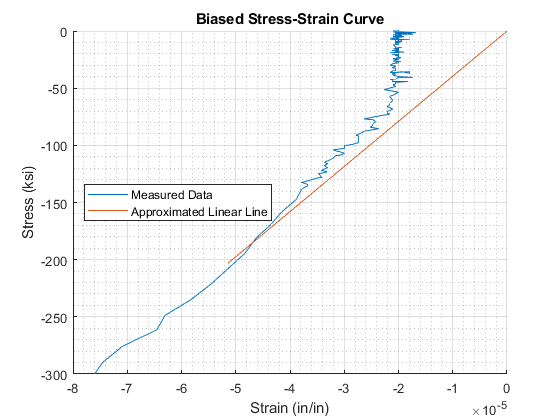

strain_bias = -2 * 10^-5; 


stress = stress + stress_bias;
strain = strain + strain_bias;

close all; figure; hold on;
plot(strain,stress,"DisplayName","Measured Data");
plot(linspace(0,strain(250)), Ec(1)*linspace(0,strain(250)),"DisplayName","Approximated Linear Line")

title("Biased Stress-Strain Curve");xlabel("Strain (in/in)"); ylabel("Stress (ksi)")
grid on; grid minor; axis([-0.00008 0 -300 0]); legend("Location","West");
print_figure(1)

[min_stress, min_id] = min(stress)

min_stress = -4.7302e+03

min_id = 1045

fc_prime = min_stress

fc_prime = -4.7302e+03

ec_prime = strain(min_id)

ec_prime = -0.0026

[~, start_id] = min(abs(-5*10^-5 - strain(1:min_id)))

start_id = 250

[~, end_id] = min(abs(0.4*fc_prime - stress(1:min_id)))

end_id = 339

coef = polyfit(strain(start_id:end_id),stress(start_id:end_id),1);
Ec_test = round(coef(1)/5,-4) *5 % Rounding the elastic modulus

Ec_test = 3200000

Ec_test/1000 % Ksi

ans = 3200

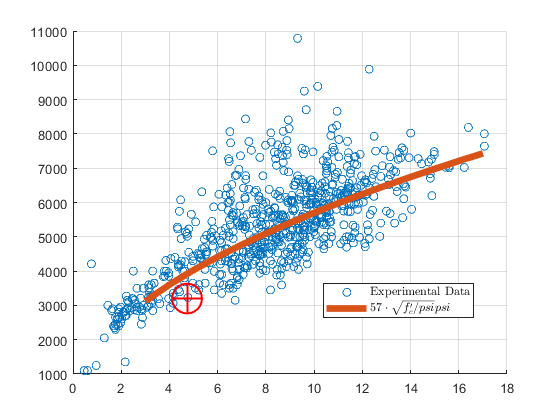

close all; hold on;
[fc, E_c] = get_Modulus_data();
scatter(fc,E_c,"Displayname","Experimental Data"); 
Ec = @(fc) 57*sqrt(fc*1000); range = 3:17;
plt = plot(range,Ec(range), 'LineWidth',5,"DisplayName","$57 \cdot \sqrt{f'_c/psi}psi$"); plt.Color(4) = 0.3;
plot_point(-fc_prime/1000, Ec_test/1000)

figure();close all; grid on; hold on; xlabel("Ratio Measured/ Predicted E_c");
% Histogram
expected_Ec = Ec(fc);
ratio_expected = E_c./expected_Ec;
mean(ratio_expected)

ans = 1.0570

median(ratio_expected)

ans = 1.0387

std(ratio_expected)

ans = 0.1966

range = 0.6:0.1:1.8;
[counts, bins]= histcounts(ratio_expected,range);
bins = bins(2:end);
yyaxis left; ylabel("Frequency");
bar(bins, counts,"DisplayName","Ratio $\frac{E_{cm}}{E_c}$");

% CDF
yyaxis right; ylabel("Culumlative Probability")
cdf = cumsum(counts) / sum(counts);
plot(bins, cdf,'r',"Marker",".", "MarkerSize",12,"DisplayName","Culumative \%");
xticks(range);
Ec = @(fc) 57000*sqrt(fc);
Ec(-fc_prime)

ans = 3.9203e+06

test_ratio = Ec_test/Ec(-fc_prime)

test_ratio = 0.8163

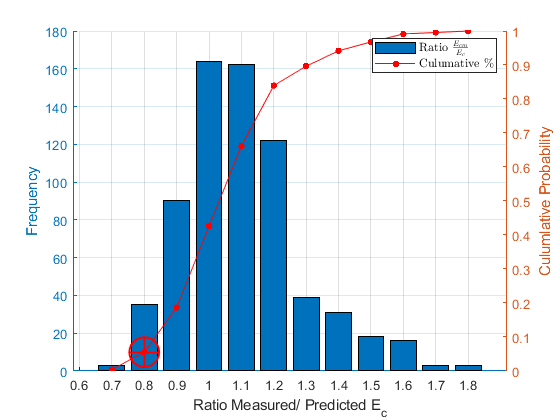

discretize(test_ratio, range);
plot_point(range(ans), cdf(ans-1));
print_figure(3)

close all; hold on;
n_test = Ec_test/(fc_prime/ec_prime)

n_test = 1.7409

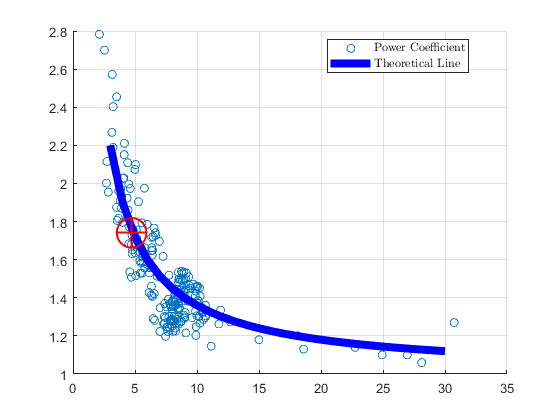

[fc, nE] = get_nE_data();
scatter(fc,nE,'DisplayName','Power Coefficient'); 
range = 3:30;
nE = @(f) 1+3.6./(f); % fc is in ksi
pl = plot(range,nE(range),'b','linewidth',6,'DisplayName','Theoretical Line'); 
plot_point(-fc_prime/1000, n_test);

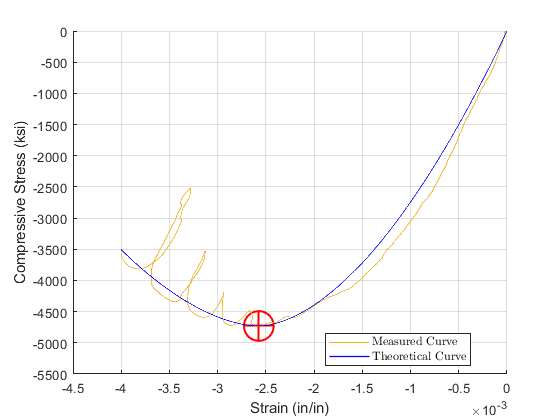

close all; hold on;
xlabel("Strain (in/in)"); ylabel("Compressive Stress (ksi)");
plot_point(strain(min_id),fc_prime)
[~, end_id] = min(abs(-4*10^-3 - strain));

plot(strain(1:end_id), stress(1:end_id),"DisplayName","Measured Curve");
nE = 1 - 3.6/fc_prime*1000;
range = linspace(strain(end_id),0,end_id);
fc = @(ec) real(fc_prime*(1-(1-abs(ec./ec_prime)).^nE)); % fc is in ksi
plot(range,fc(range),'Color',[0, 0, 1],'linewidth',1,'DisplayName','Theoretical Curve');
print_figure(5); ylim([-5500 0])

close all; hold on;  axis([-9*10^-3 0 -5000 0]);
[~, end_id] = min(abs(0.4*fc_prime - stress(min_id:end))); end_id = end_id + min_id% Finding where stress = 0.4*f'c after the peak

end_id = 3513

eta = (stress(end_id) - fc_prime)/(strain(end_id)-ec_prime)/ Ec_test % Find the eta value

eta = -0.2762

linear_elastic = @(ec, e, f) Ec_test*(ec-e) +f; % Function for linear line
post_peak = @(ec) eta*Ec_test*(ec-ec_prime) +fc_prime; % Function for post peak 

linear_elastic_range = linspace(strain(min_id),0,100); % Linear elastic straings
post_peak_range = linspace(strain(min_id),ec_prime - fc_prime/eta/Ec_test,100); % Post Preak Range

plot(strain(1:end_id), stress(1:end_id),"DisplayName","Test Result"); % Test data
plot(linear_elastic_range,linear_elastic(linear_elastic_range,0,0),"DisplayName","Linear Elastic"); % Linear Elastic
plot(linear_elastic_range,linear_elastic(linear_elastic_range,ec_prime,fc_prime),"DisplayName","Unloading at Peak"); %Unloading
plot_point(strain(min_id),fc_prime); plot_point(strain(end_id),stress(end_id)); % Big Red Points

plot(post_peak_range,post_peak(post_peak_range),"DisplayName","Post Peak Response");
xlabel("Strain (in/in)"); ylabel("Compressive Stress (ksi)")
e_cu = fc_prime * (1/eta/Ec_test + 1/-Ec_test)

delta_ppk = 0.0068

delta_ppk = e_cu * 8

ans = 0.0546

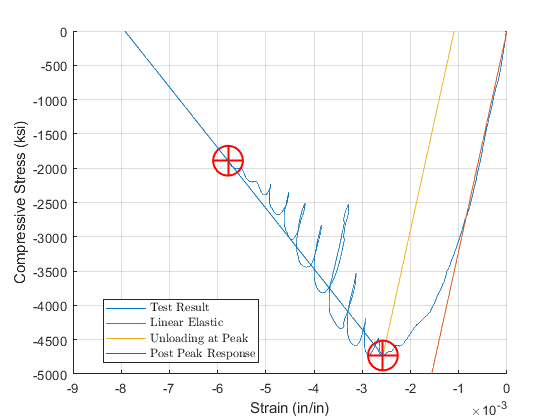

print_figure(6)

function [strain, stress] = get_data()
    opts = spreadsheetImportOptions("NumVariables", 2);
    opts.Sheet = "Cylinder test data"; % Specify sheet and range
    opts.DataRange = "A6:B8491";
    opts.VariableNames = ["Strain", "Stress"]; % Specify column names and types
    opts.VariableTypes = ["double", "double"];
    tbl = readtable("C:\Users\Louis Lin\Workspace\Academic\UCSD\SE 211\Homework\HW 2\data\SE211 HW2 2021 Students.xlsx", opts, "UseExcel", false); % Import the data
    strain = tbl.Strain; stress = tbl.Stress;
end

function [fc, Ec] = get_Modulus_data()
    opts = spreadsheetImportOptions("NumVariables", 2);
    opts.Sheet = "Ec (NCHRP 496)";
    opts.DataRange = "B10:C698";
    opts.VariableNames = ["fc1", "Ec"];
    opts.VariableTypes = ["double", "double"];
    tbl = readtable("C:\Users\Louis Lin\Workspace\Academic\UCSD\SE 211\Homework\HW 2\data\SE211 HW2 2021 Students.xlsx", opts, "UseExcel", false);
    fc = tbl.fc1; Ec = tbl.Ec;
end

function [fc, nE] = get_nE_data()
    opts = spreadsheetImportOptions("NumVariables", 2);
    opts.Sheet = "nE";
    opts.DataRange = "C4:D212";
    opts.VariableNames = ["fc1", "nE"];
    opts.VariableTypes = ["double", "double"];
    tbl = readtable("C:\Users\Louis Lin\Workspace\Academic\UCSD\SE 211\Homework\HW 2\data\SE211 HW2 2021 Students.xlsx", opts, "UseExcel", false);
    fc = tbl.fc1; nE = tbl.nE;
end

function plot_point(x,y)
    scatter(x, y,500,'red','+','LineWidth',1.5,'HandleVisibility',"off"); 
    scatter(x, y,500,'red','o','LineWidth',1.5,'HandleVisibility',"off");
    legend('Interpreter',"latex",'Location',"best"); grid on; 
end

function print_figure(no)
    % Saves the figures in a consistent manner
    orient(gcf,'landscape');
    folder = '..\figures\';
    name = 'Figure' +string(no);
    print(folder+name,'-dpdf','-fillpage','-PMicrosoft Print to PDF','-r600','-painters')
    print(folder+name,'-djpeg','-PMicrosoft Print to PDF','-r600','-painters')
end